In addition to typical data analysis, MATLAB is well-suited to image analysis due to its matrix operations. In this section we will explore some of its mapping capabilities and image analysis functions. Whilst other forms of software are useful for image analysis, MATLAB has some additional benefits, one of which is the reproducibility of maps created and analysis that you undertake, also enabling a reader to produce a map and explore it dynamically. Let's start by using some Landsat 8 imagery downloaded from [GloVis](https://glovis.usgs.gov/app?fullscreen=0) of a study site in the UK. We will first download the required datasets:

clear all; close all; clc

dirIn = 'C:\_git_local\GEO8026_21_22\Block 05\data\esk\'; % modify as required
addpath(genpath( 'C:\_git_local\GEO8026_21_22\Block 05\code'));

Let's plot the raw imagery without any manipulation of the bands

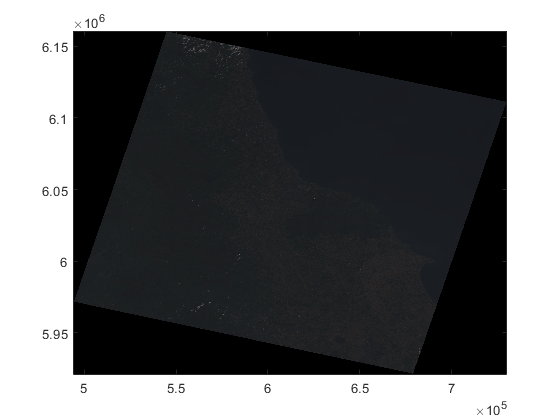

filename = ...
    'LC08_L1TP_203022_20210907_20210916_01_T1_';
channels = ['B4';'B3';'B2';'B5']; % red, green, blue, nir
extension = '.TIF';

[B4,R]  = readgeoraster([dirIn, filename,channels(1,:),extension]); % read georaster can read in geotiff files
[B3]    = readgeoraster([dirIn, filename,channels(2,:),extension]);
[B2]    = readgeoraster([dirIn, filename,channels(3,:),extension]);
[B5]    = readgeoraster([dirIn, filename,channels(4,:),extension]);
[x,y]   = pixcenters(R,R.YIntrinsicLimits(2),R.XIntrinsicLimits(2));

% RGB conversions for display purposes:
bands{1} = im2double(B4);   % Red channel
bands{2} = im2double(B3);   % Green channel
bands{3} = im2double(B2);   % Blue channel

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

figure();
h2 = image(x,y,RGBImage);  
set(gca, 'YDir','normal');

As you can see, the image is very dark. This is because the histogram is not optimised for visualisation purposes. Let's look at the histogram of the rgb values:

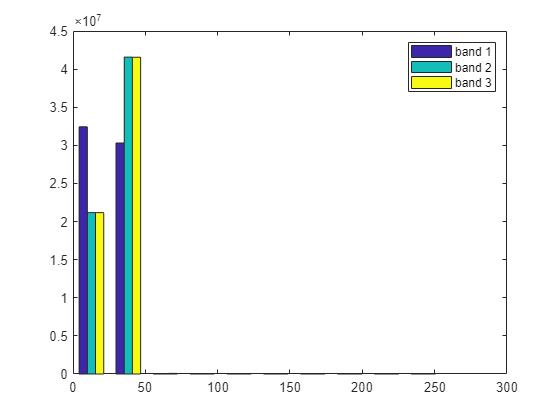


out(:,1) = double(reshape(RGBImage(:,:,1),[],1));
out(:,2) = double(reshape(RGBImage(:,:,2),[],1));
out(:,3) = double(reshape(RGBImage(:,:,3),[],1));
hist(out);
legend('band 1', 'band 2', 'band 3');

We can see that all of the values are skewed to the left of the scale (i.e. < 50), whereas the range of possible color values spans from 0 - 255. We can modify the distribution to improve the way that the image looks:

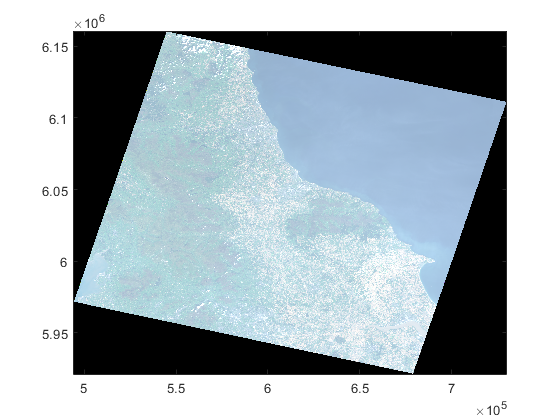

bands{1} = imadjust(bands{1}, stretchlim(bands{1}));       % Adjustment on Red channel
bands{2} = imadjust(bands{2}, stretchlim(bands{2}));       % Adjustment on Green channel
bands{3} = imadjust(bands{3}, stretchlim(bands{3}));       % Adjustment on Blue channel

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

figure();
h2 = image(x,y,RGBImage);  
set(gca, 'YDir','normal')

This looks a lot better but from the histogram we can see that the values are now skewed to the right. Let's try one more command:

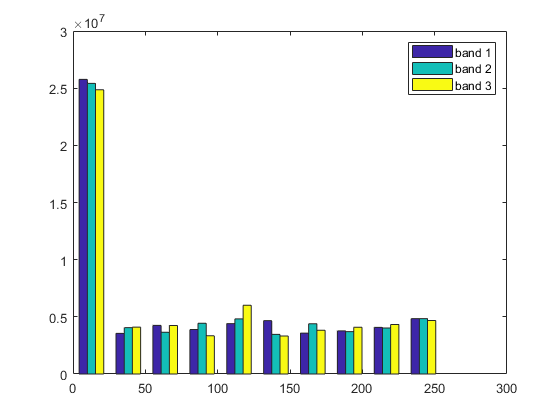


bands{1} = histeq(bands{1});                               % histeq on Red channel
bands{2} = histeq(bands{2});                               % histeq on Green channel
bands{3} = histeq(bands{3});                               % histeq on Blue channel

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

out(:,1) = double(reshape(RGBImage(:,:,1),[],1));
out(:,2) = double(reshape(RGBImage(:,:,2),[],1));
out(:,3) = double(reshape(RGBImage(:,:,3),[],1));
hist(out)
legend('band 1', 'band 2', 'band 3')
hold off;

Now the image is the way that we want it to look, we can bring in additional features, for example ESRI shapefiles. We just need to make sure that they are in the same projected coordinate system. In this case, both the imagery and shapefiles are in UTM Zone 30N:

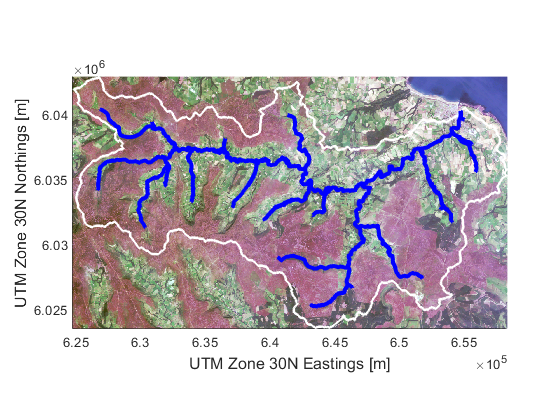

figure(); hold on;
h2 = image(x,y,RGBImage);  
set(gca, 'YDir','normal');

x_lims = [624800 658300];
y_lims = [6023500,6042900];
axis equal
set(gca,'xlim',x_lims);
set(gca,'ylim',y_lims);

S       = shaperead([dirIn, '\catchment_utm.shp']); % Load in the catchment outline
h1      = plot(S.X,S.Y,'w'); hold on % Plot the catchment outline;
set(h1,'LineWidth',2);
S2      = shaperead([dirIn, '\drainage_utm.shp']); % Load in the river network
for a = 1:length(S2)
    h2 = plot(S2(a).X,S2(a).Y,'b'); set(h2,'LineWidth',3); % Plot the river network
end

hXlabel = xlabel('UTM Zone 30N Eastings [m]'); % Create xlabel
hYlabel = ylabel('UTM Zone 30N Northings [m]'); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);